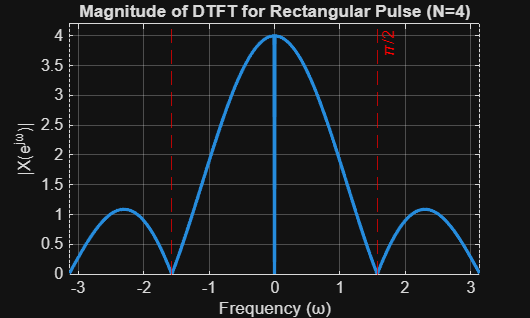

% Q.1 a)
% Define the frequency vector (omega) from -pi to pi
w = -pi:pi/500:pi;

% Define the length of the pulse
N = 4;

% Calculate the magnitude response using the Dirichlet Sinc formula.
% Adding a small constant (eps) to the denominator prevents division by zero at w=0.
magnitude_X = abs(sin(N*w/2) ./ (sin(w/2) + eps));

% Plot the Magnitude Response
figure;
plot(w, magnitude_X, 'LineWidth', 2);
title('Magnitude of DTFT for Rectangular Pulse (N=4)');
xlabel('Frequency (ω)');
ylabel('|X(e^{jω})|');

% Mark the key features:
% Peak is 4 at w=0
% Zero crossings at w = +/- pi/2, +/- pi, +/- 3pi/2, etc.

xline(pi/2, 'r--', 'Label', '\pi/2');
xline(-pi/2, 'r--');
xline(pi, 'k:', 'Label', '\pi');
xline(-pi, 'k:');

xlim([-pi pi]);
ylim([0 4.2]);
grid on;

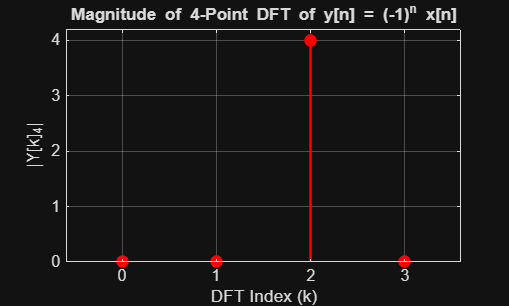

% Q.1d)
% Define the DFT indices (k)
k = 0:3;

% Define the magnitude values |Y[k]_4|
% The sequence is [Magnitude at k=0, Magnitude at k=1, Magnitude at k=2, Magnitude at k=3]
magnitude_Y_k = [0, 0, 4, 0];

% Plot the DFT magnitude using a stem plot
figure;
stem(k, magnitude_Y_k, 'r', 'filled', 'LineWidth', 1.5);
title('Magnitude of 4-Point DFT of y[n] = (-1)^n x[n]');
xlabel('DFT Index (k)');
ylabel('|Y[k]_4|');
xticks(k); % Ensure ticks are only at integer indices
ylim([0 4.2]);
grid on;